# Immo

Inspiration: [https://github.com/slevin48/immo](https://github.com/slevin48/immo)

Data source: [https://www.data.gouv.fr/fr/datasets/5cc1b94a634f4165e96436c1/](https://www.data.gouv.fr/fr/datasets/5cc1b94a634f4165e96436c1/) 

Example in Paris (14th arrondissement)

commune = "75114";
price_min = 7500;
price_max = 12000;
date_start = datetime("2023-03-14", "InputFormat", "uuuu-MM-dd");

T = load_data(commune);
T = T(T.prixm2 > price_min & T.prixm2 < price_max & T.date_mutation > date_start,{'id_mutation','date_mutation','valeur_fonciere','prixm2','adresse_numero','adresse_nom_voie','latitude','longitude','marker_color'})

T = 369x9 table
      id_mutation      date_mutation    valeur_fonciere    prixm2    adresse_numero        adresse_nom_voie         latitude    longitude    marker_color
    _______________    _____________    _______________    ______    ______________    _________________________    ________    _________    ____________

    {'2023-563047'}     30-Jun-2023        4.908e+05       10016            3          {'RUE FURTADO HEINE'    }      48.83      2.3196       {'red'   } 
    {'2023-563211'}     30-Jun-2023        1.275e+06       11486           21          {'VLA D ALESIA'         }     48.828      2.3242       {'red'   } 
    {'2023-563217'}     30-Jun-2023         6.15e+05       10

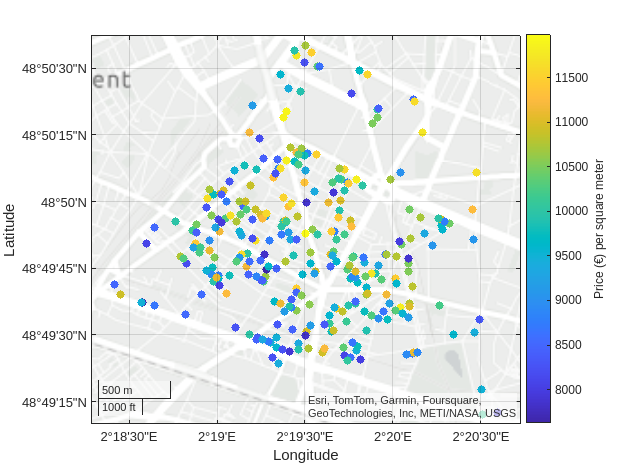

s = geoscatter(T,"latitude","longitude","filled");
s.ColorVariable = "prixm2";
c = colorbar;
c.Label.String = "Price (€) per square meter";

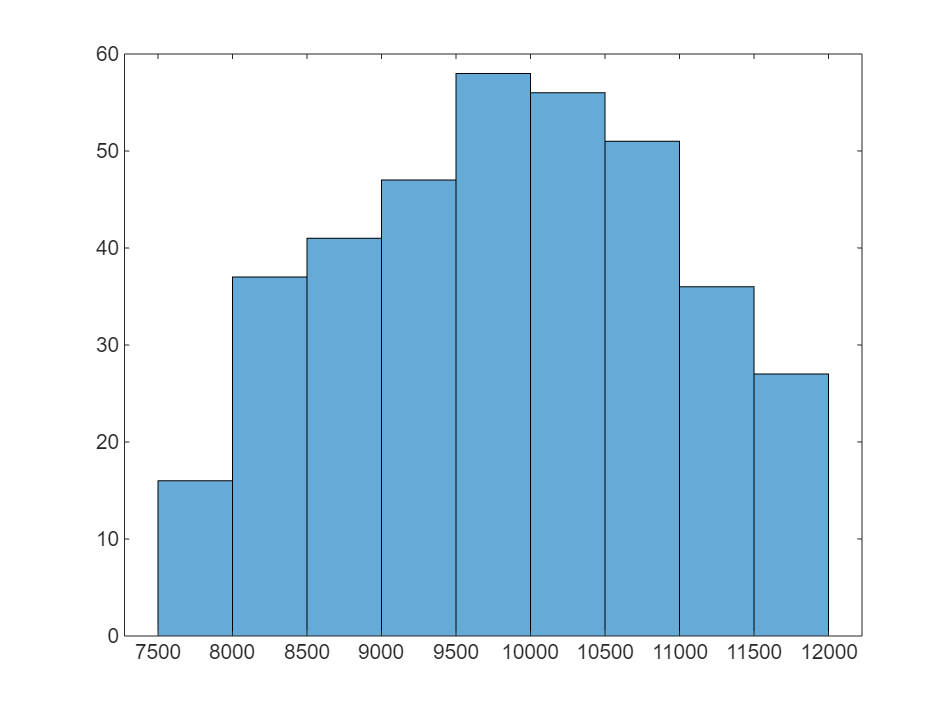

histogram(T.prixm2)

function T = load_data(code_commune)
    commune_str = num2str(code_commune);
    % Construct the URL from the commune code
    url = ['https://files.data.gouv.fr/geo-dvf/latest/csv/2023/communes/', ...
           commune_str(1:2) '/', commune_str, '.csv'];
       
    % Read the CSV data from the URL
    opts = detectImportOptions(url, 'DatetimeType', 'text'); % Adjust import options if necessary
    T = readtable(url, opts);
    
    % Convert date_mutation to datetime
    T.date_mutation = datetime(T.date_mutation, 'InputFormat', 'yyyy-MM-dd');
    
    % Drop rows with missing values in specified columns
    T = rmmissing(T, 'DataVariables', {'valeur_fonciere', 'surface_reelle_bati', 'longitude', 'latitude'});
    
    % Calculate price per m2 and filter
    T.prixm2 = T.valeur_fonciere ./ T.surface_reelle_bati;
    T = T(T.prixm2 > 1000 & T.prixm2 < 15000, :);
    
    % Convert prixm2 to integer
    T.prixm2 = int32(T.prixm2);
    
    % Assign marker colors based on prixm2 value
    edges = [0, 2500, 5000, 10000, 15000]; % Adjust bins as needed
    [~, ~, bins] = histcounts(T.prixm2, edges);
    colors = {'blue', 'green', 'yellow', 'red'};
    T.marker_color = colors(bins)';
    
    % Sort by date_mutation
    T = sortrows(T, 'date_mutation', 'descend');
end

% % Example usage:
% commune = 75114;
% T = load_data(commune)